# TRIG_FSERIES

Calculation of Fourier coefficients for Square Wave

Note the Fourier Series coefficients are computed using the period and fundamental frequency rather than the radian measures given in the lecture.

Prepared for EG-247 Signals and Systems by Chris Jobling

clear all
%

## Initialize problem

syms t n A u0 f(t)
%

## Redefine `heaviside` function to match mathematics

u0(t) = heaviside(t);

## Set up problem

f0 = 1000;         % Hz
T0 = 1/f0;          % s
omega_0 = 2*pi/T0; % rad/s

## Define harmonics

k_max = 11;

## Define f(t)

!!!IMPORTANT!!!: the signal definition must cover [0 to T0]

So I've sythesized two periods so we can easily shift the waveform later. 

It's a good idea to plot the waveform so you can check it's OK!

% first period
f(t) = A*(u0(t)-u0(t-T0/2)) - A*(u0(t-T0/2) - u0(t-T0));
% Add second period - f(t) delayed by T0
f(t) = f(t) + f(t-T0)

$$f(t) = A\,\left(\mathrm{heaviside}\left(t-\frac{1}{500}\right)-\mathrm{heaviside}\left(t-\frac{3}{2000}\right)\right)-A\,\left(\mathrm{heaviside}\left(t-\frac{1}{2000}\right)-\mathrm{heaviside}\left(t\right)\right)+A\,\left(\mathrm{heaviside}\left(t-\frac{1}{1000}\right)-\mathrm{heaviside}\left(t-\frac{1}{2000}\right)\right)+A\,\left(\mathrm{heaviside}\left(t-\frac{1}{1000}\right)-\mathrm{heaviside}\left(t-\frac{3}{2000}\right)\right)$$

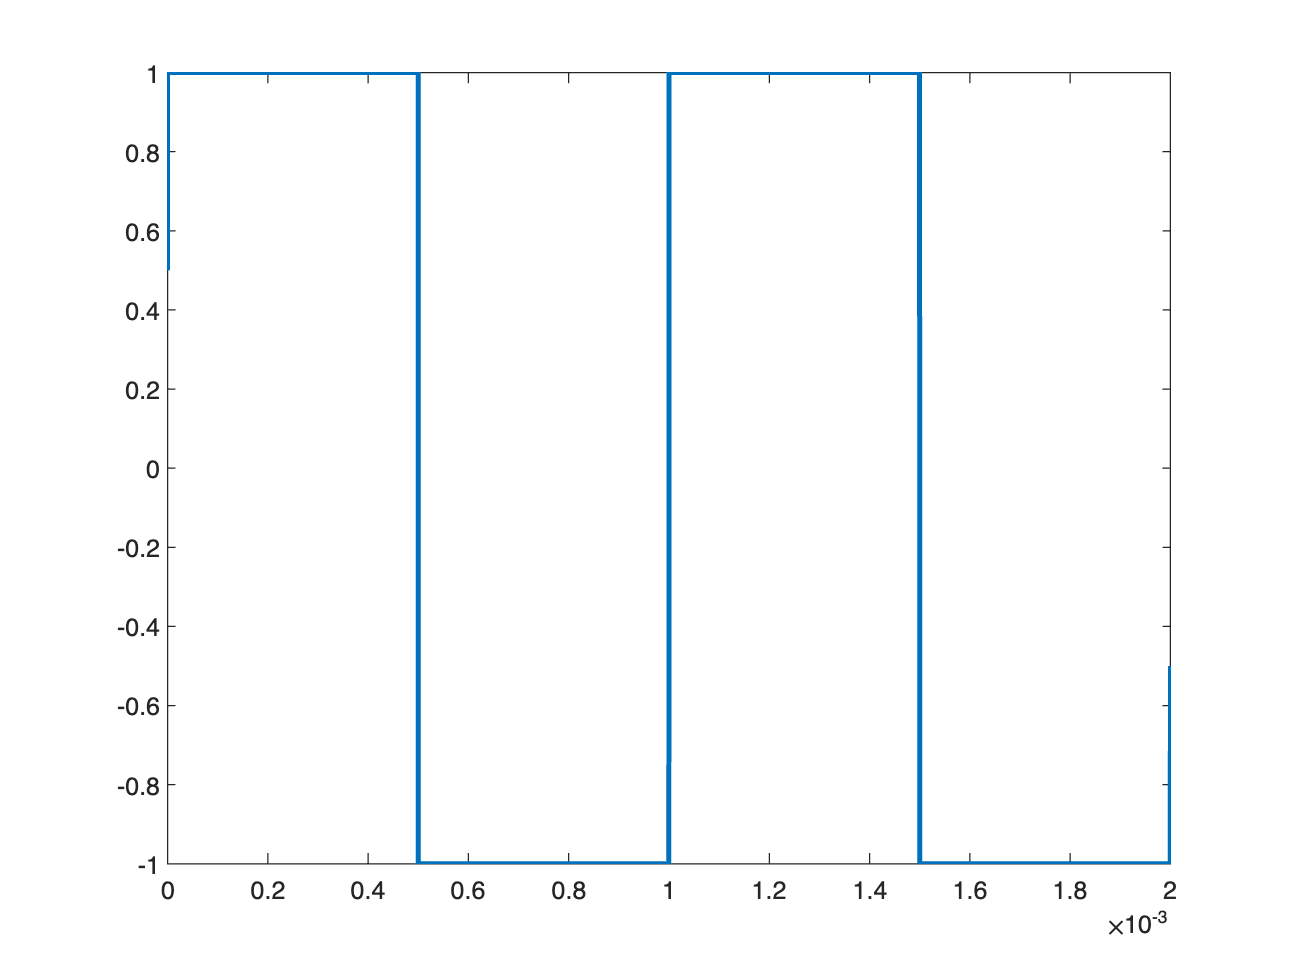

fplot(subs(f(t),A,1),[0,2*T0],'LineWidth',2)

## Compute TFS

Note that this can take considerable time (6 minutes or more) so be patient! 

[a0, ak, bk, w] = TrigFourierSeries(f(t), T0, k_max)

$$a0 = 0$$

$$a0 = 0$$

$$ak = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$bk = \left(\begin{array}{ccccccccccc} \frac{4\,A}{\pi } & 0 & \frac{4\,A}{3\,\pi } & 0 & \frac{4\,A}{5\,\pi } & 0 & \frac{4\,A}{7\,\pi } & 0 & \frac{4\,A}{9\,\pi } & 0 & \frac{4\,A}{11\,\pi } \end{array}\right)$$

w = 1.0e+04 *

    0.6283    1.2566    1.8850    2.5133    3.1416    3.7699    4.3982    5.0265    5.6549    6.2832    6.9115         0    0.6283    1.2566    1.8850    2.5133    3.1416    3.7699    4.3982    5.0265    5.6549    6.2832    6.9115


## Reconstruct f(t) from harmonic sine functions

Ft = a0/2;
for k=1:k_max
    Ft = Ft + ak(k)*cos(w(k)*t) + bk(k)*sin(w(k)*t);
end
Ft

$$Ft = \frac{4\,A\,\sin\left(2000\,\pi \,t\right)}{\pi }+\frac{4\,A\,\sin\left(6000\,\pi \,t\right)}{3\,\pi }+\frac{4\,A\,\sin\left(10000\,\pi \,t\right)}{5\,\pi }+\frac{4\,A\,\sin\left(14000\,\pi \,t\right)}{7\,\pi }+\frac{4\,A\,\sin\left(18000\,\pi \,t\right)}{9\,\pi }+\frac{4\,A\,\sin\left(22000\,\pi \,t\right)}{11\,\pi }$$

## Make numeric

a0_num = subs(a0,A,1.0);
ak_num = subs(ak,A,1.0);
bk_num = subs(bk,A,1.0);

## print using 4 sig digits

a0_num = vpa(a0_num, 4)

$$a0\_num = 0.0$$

ak_num = vpa(ak_num, 4)

$$ak\_num = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

bk_num = vpa(bk_num, 4)

$$bk\_num = \left(\begin{array}{ccccccccccc} 1.273 & 0 & 0.4244 & 0 & 0.2546 & 0 & 0.1819 & 0 & 0.1415 & 0 & 0.1157 \end{array}\right)$$

## plot result and original signal

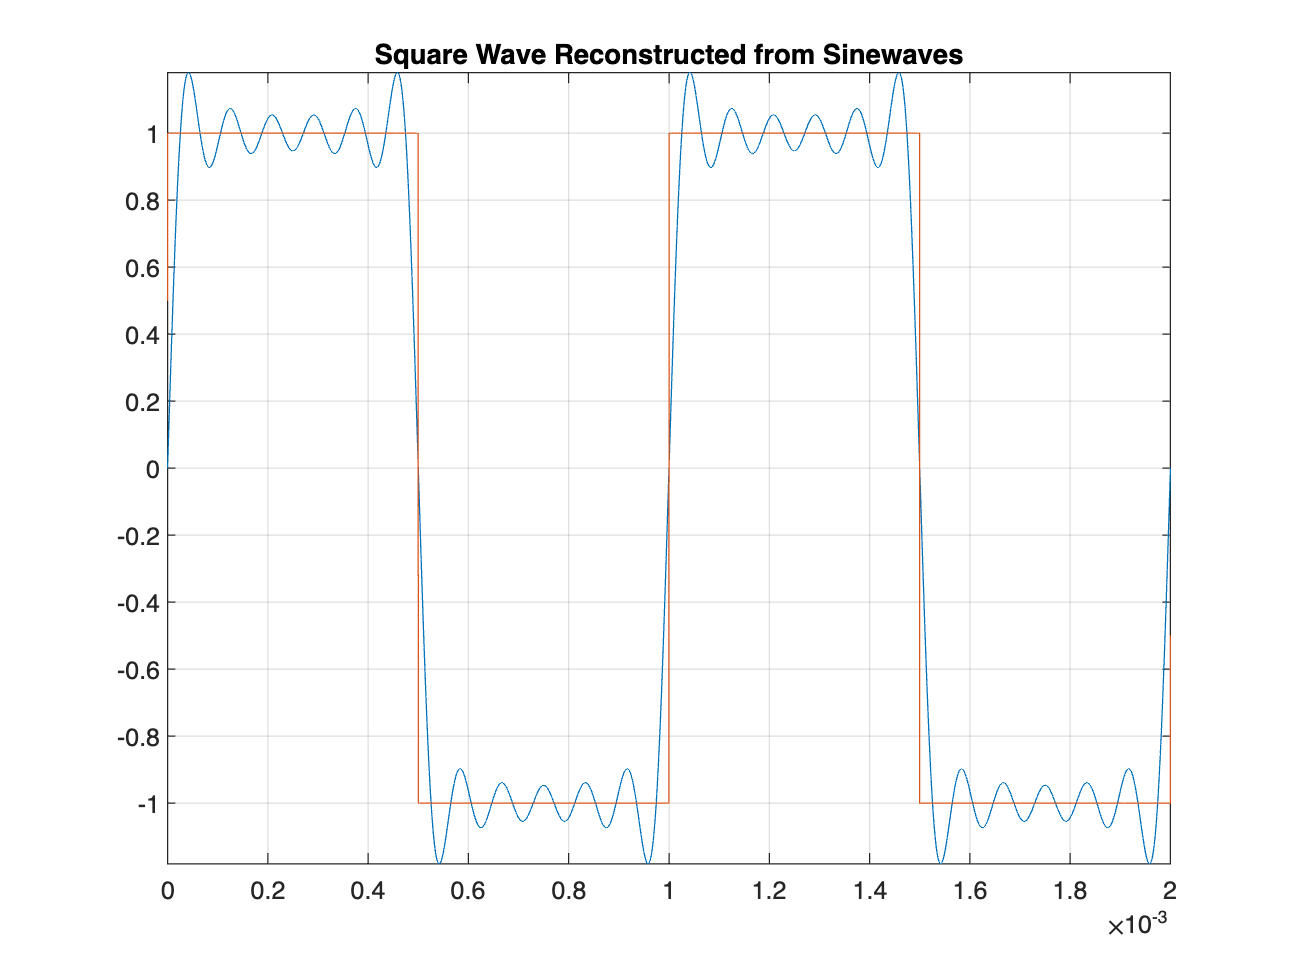

fplot([subs(Ft,A,1),subs(f(t),A,1)],[0,2*T0]),grid
title('Square Wave Reconstructed from Sinewaves')
hold off